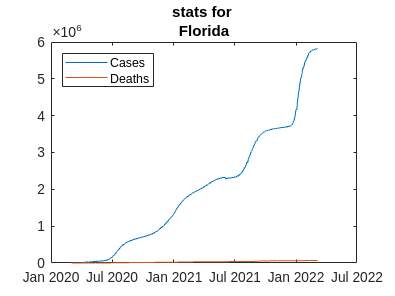

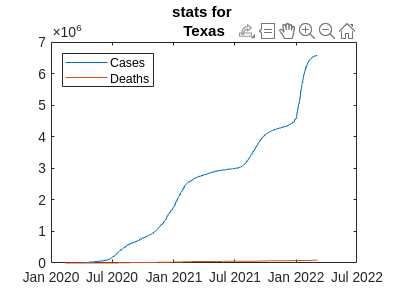

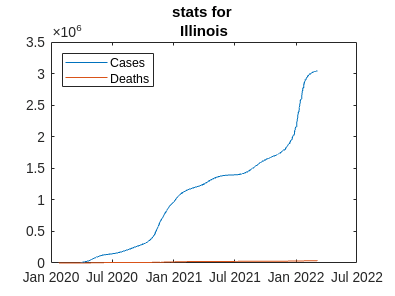

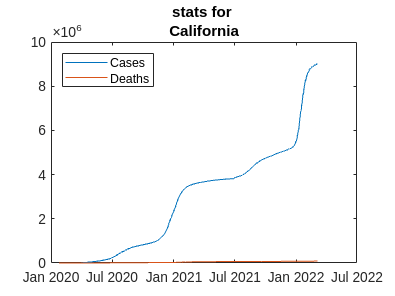

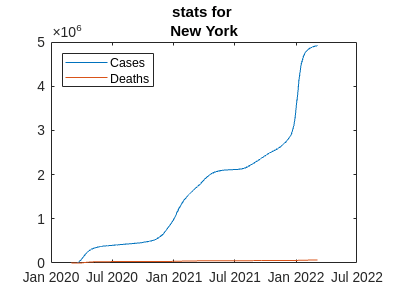

clf;

data = readtable('us-states.csv');
states = ["Florida","Texas","Illinois","California","New York"];

for i=1:numel(states)
    
    state = states(i);
    T = data(strcmp(data.state,state),:);
    
    f = figure;
    plot(T.date,[T.cases,T.deaths]);
    title(['stats for ',state]);
    legend({'Cases','Deaths'},'Location','northwest');

end